# ECSE 343:Assignment 4

Name: Karen Cherry Chen Lai

Student Id: 261107674

Due Date: 12 April 2024

## Question 1

 You are given the following 3rd order differential equation,

                
$$y^{'''}(t) + 32 y^{''} (t) +61.25 y'(t)  + 37.5 y(t)  = sin(\frac{\pi t} {4})$$


a. Transform the above differential equation into a system of first-order differential equations. **(5 marks)**

*        % Show all your work here. Write all your steps and equations.*

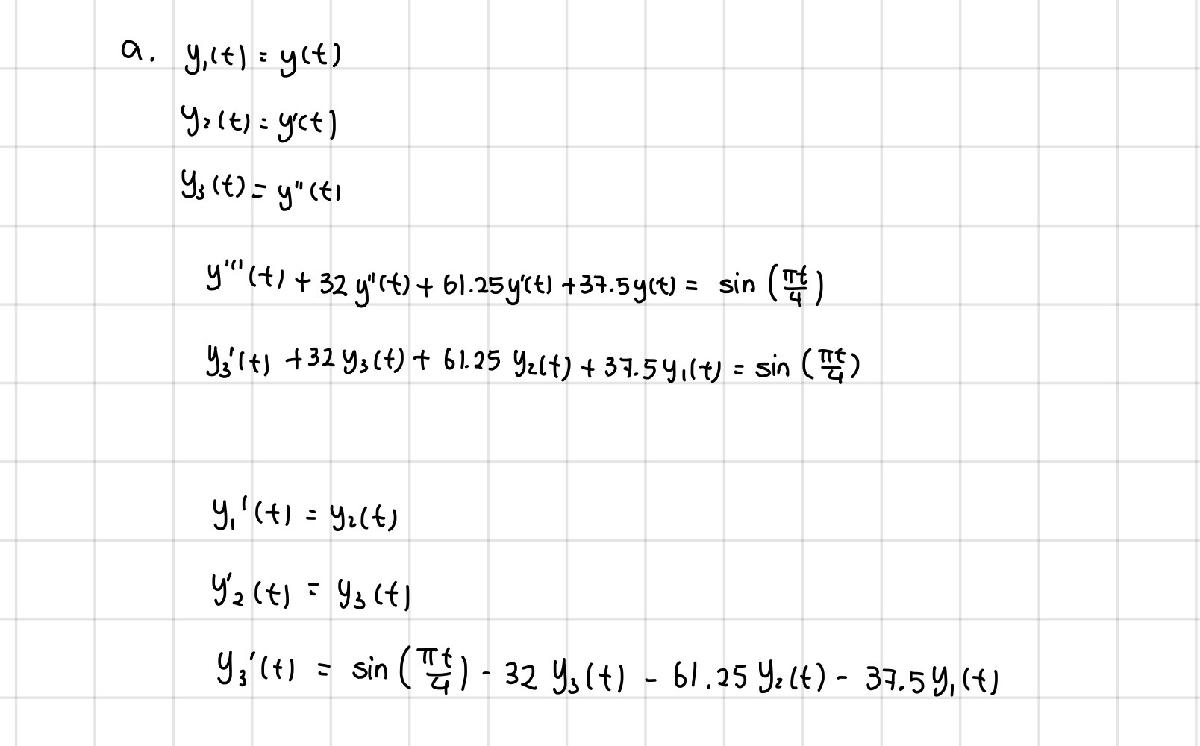

b.  For the system of first order ODEs obtained in part a, apply the Backward Euler approximation for the derivative and write the obtained **difference Equations **below. **(5 marks)**

*        % type your answer here, write all the equations*

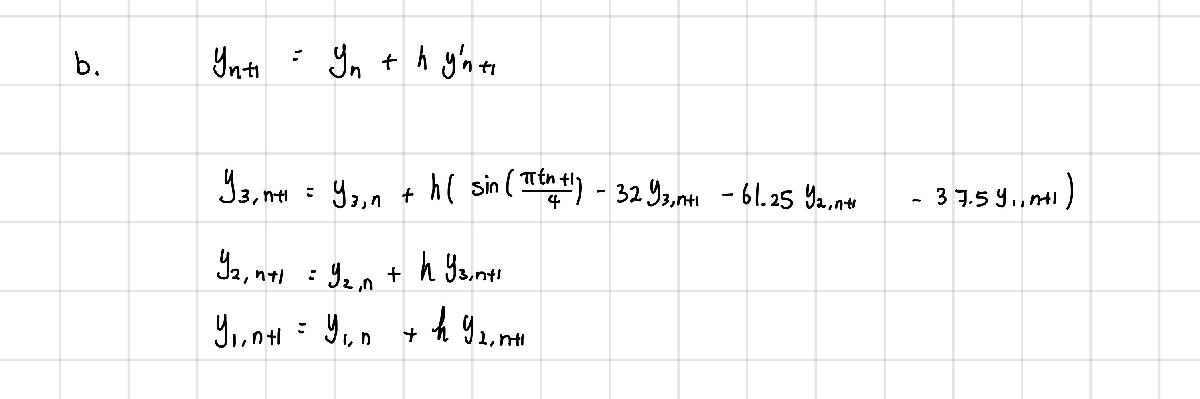

c.  You are provided with the initial conditions, $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$ for the given differential equation.  Use the cell below to implement the Backward Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  

Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

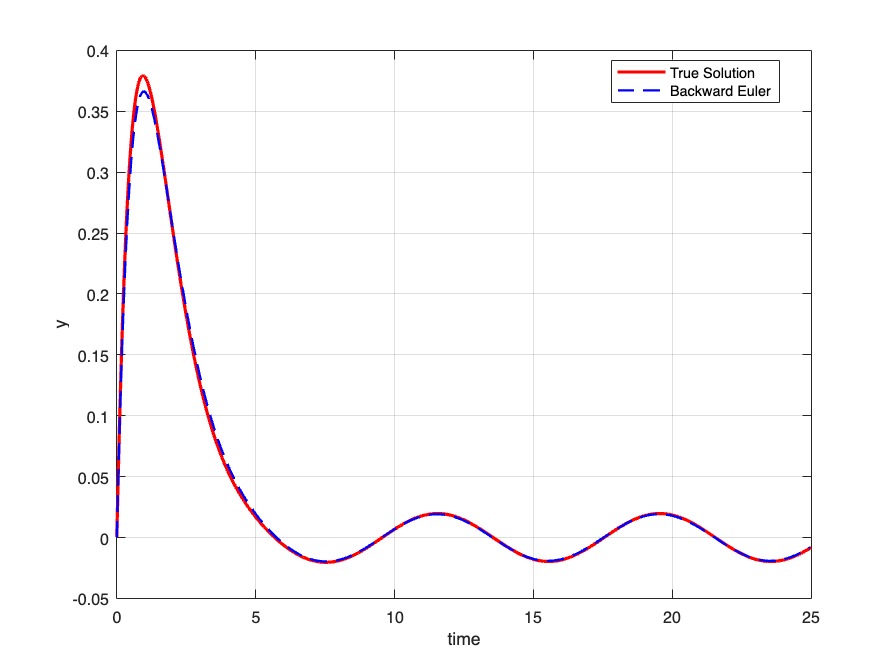

clear all
dT = 0.065; %sec
T = 0:dT:25;  % time vector with 25 as total time

%-----------------------------------------------------------------------------
% write the your code here.
% Initial conditions
y1 = 0; % y(0)
y2 = 1; % y'(0)
y3 = 0; % y''(0)

Y = zeros(3, length(T)); % Preallocate the results array
Y(:,1) = [y1; y2; y3];

options = optimoptions('fsolve', 'Display', 'none');

for n = 1:(length(T)-1)
    fun = @(Y_next) [
        Y_next(1) - Y(1,n) - dT * Y_next(2);
        Y_next(2) - Y(2,n) - dT * Y_next(3);
        Y_next(3) - Y(3,n) - dT * (sin(pi*(T(n)+dT)/4) - 32*Y_next(3) - 61.25*Y_next(2) - 37.5*Y_next(1))
    ];
    
    Y_next = fsolve(fun, Y(:,n), options); % next step
    
    Y(:,n+1) = Y_next; % update result array
end
%------------------------------------------------------------------------------
load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 4/q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,Y(1,:),'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

d.  Run the code you wrote in part c again, run the code for $25s$ and use the time step $\Delta t= 1s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

 Is the obtained solution more accurate than the solution in part c? Explain.  **(2 marks)**

*Note: You may copy the code you wrote in part c in the cell below to run it for *$\Delta t =1s$ 

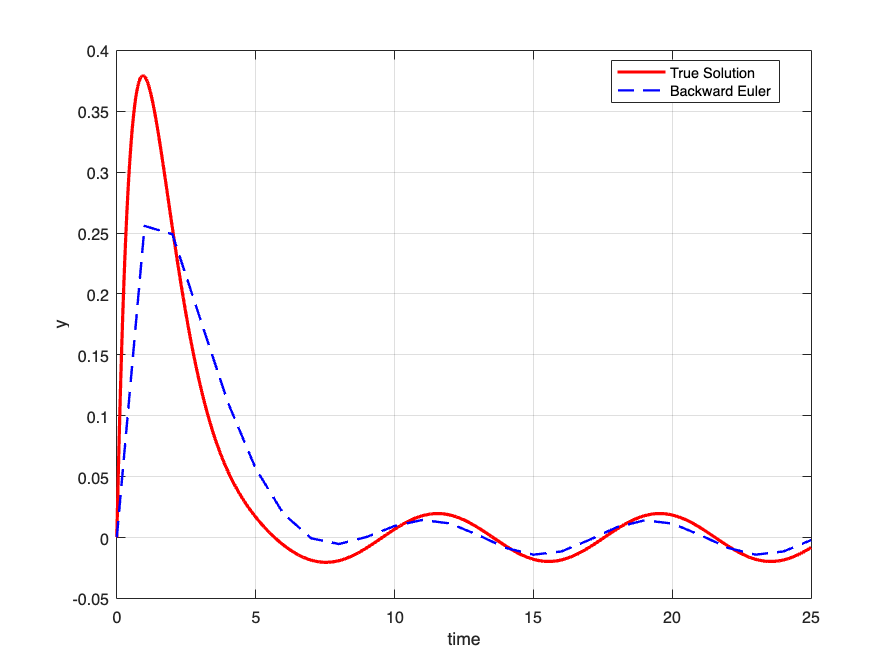

% you may copy the code from part c here and run it for deltaT =1s
clear all
dT = 1; %sec
T = 0:dT:25;  % time vector with 25 as total time

%-----------------------------------------------------------------------------
% write the your code here.
% Initial conditions
y1 = 0; % y(0)
y2 = 1; % y'(0)
y3 = 0; % y''(0)

Y = zeros(3, length(T)); % Preallocate the results array
Y(:,1) = [y1; y2; y3];

options = optimoptions('fsolve', 'Display', 'none');

for n = 1:(length(T)-1)
    fun = @(Y_next) [
        Y_next(1) - Y(1,n) - dT * Y_next(2);
        Y_next(2) - Y(2,n) - dT * Y_next(3);
        Y_next(3) - Y(3,n) - dT * (sin(pi*(T(n)+dT)/4) - 32*Y_next(3) - 61.25*Y_next(2) - 37.5*Y_next(1))
    ];
    
    Y_next = fsolve(fun, Y(:,n), options); % next step
    
    Y(:,n+1) = Y_next; % update result array
end
%------------------------------------------------------------------------------
load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 4/q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,Y(1,:),'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*% COMMENT: It is obvious that the solution of part d) is less accurate than the one in part c). The backward euler dashed line is much more fitting to the solution in part c). Thus, it implies that it has more numerical errors in part d).*

e. For the system of first-order ODEs obtained in part a, use the Forward Euler approximation for the derivative and write the obtained difference Equations below. **(5 marks)**

*        %  type your answer here. Show all the equations and steps.*

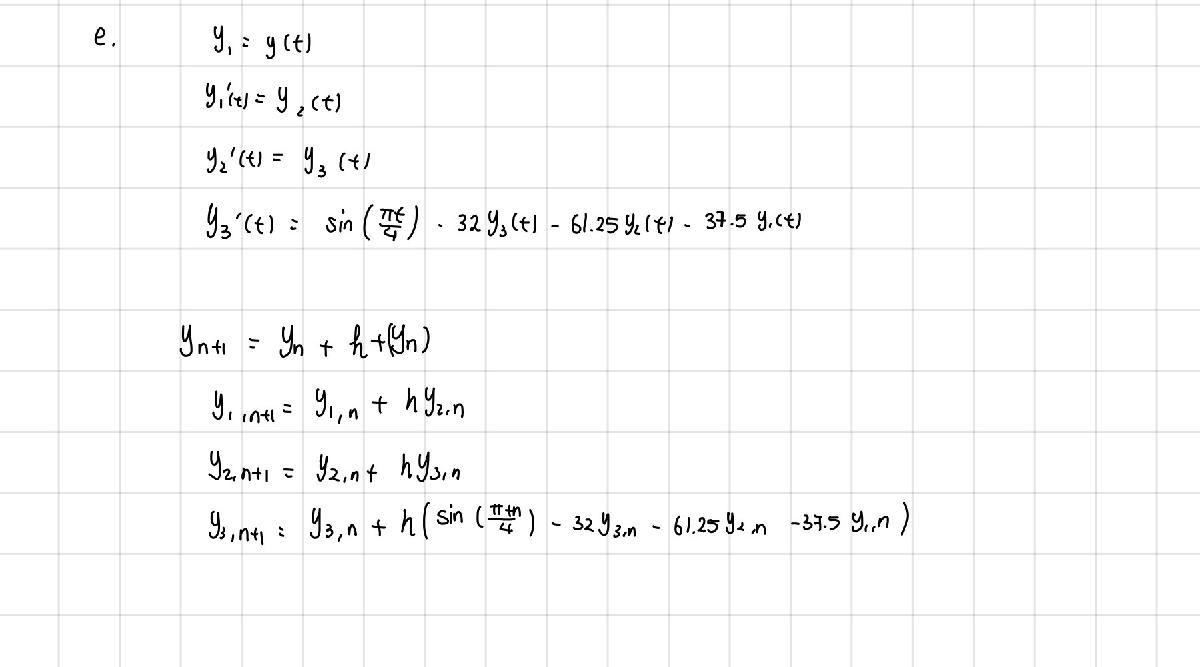

f. Use the same initial conditions as part c (i.e. $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$).  Implement the Forward  Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

Write your code in the cell below.

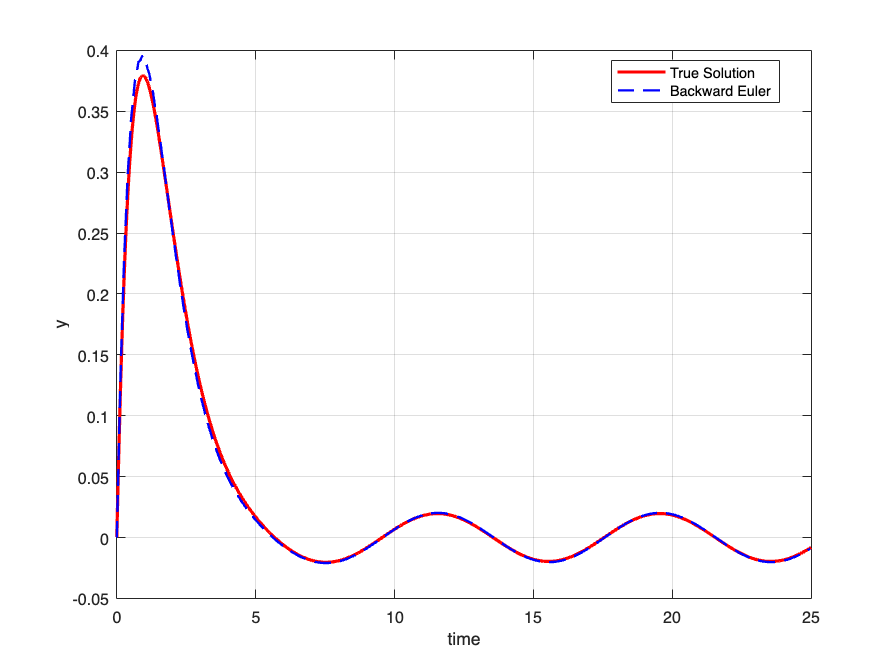

clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.
y1 = 0; 
y2 = 1; 
y3 = 0;

Y = zeros(3, length(T));
Y(:, 1) = [y1; y2; y3];

a = 32;
b = 61.25;
c = 37.5;

for n = 1:length(T)-1
    % y1 update
    Y(1, n+1) = Y(1, n) + dT * Y(2, n); 
    % y2 update
    Y(2, n+1) = Y(2, n) + dT * Y(3, n); 
    % y3 update
    Y(3, n+1) = Y(3, n) + dT * (sin(pi*T(n)/4) - a*Y(3, n) - b*Y(2, n) - c*Y(1,n)); 
end
%------------------------------------------------------------------------------
load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 4/q1_refSol.mat') % load true analytical sol for reference.
figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------
% plot your solution here.
plot(T,Y(1, :),'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

g. Run the code you wrote in part f again, run the code for $25s$ and use the time step $\Delta t= 0.068s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

*Note: You may copy the code you wrote in part f in the cell below to run it for *$\Delta t =0.068s$ 

Comment on the solutions obtained in part e and f. **(2 marks)**

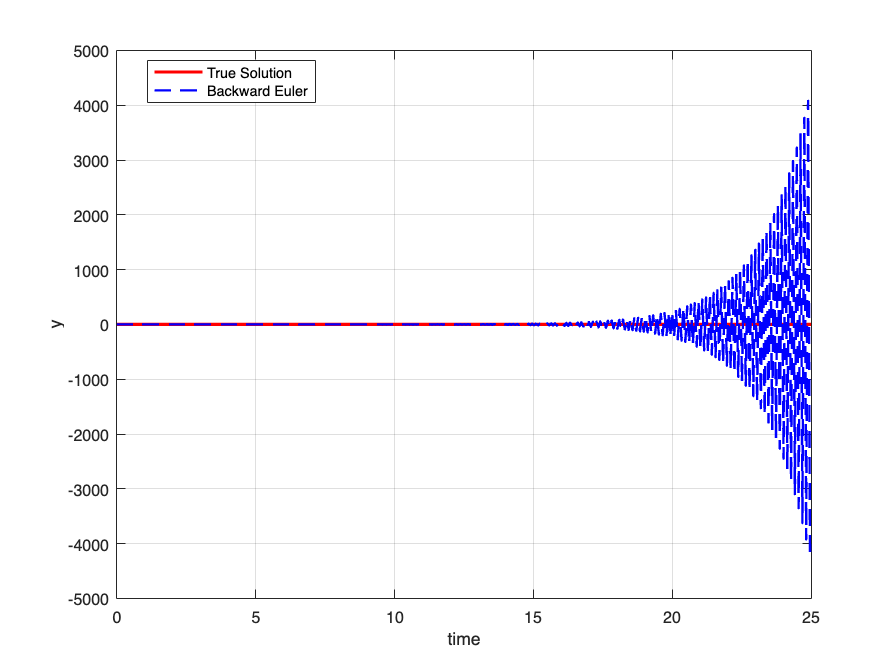

% you may copy the code from part c here and run it for deltaT =1s
clear all
dT = 0.068; %sec
T = 0:dT:25;  % time vector with 25 as total time

%-----------------------------------------------------------------------------
% write the your code here.
 
y1 = 0; % Initial y(t)
y2 = 1; % Initial y'(t)
y3 = 0; % Initial y''(t)

Y = zeros(3, length(T));
Y(:, 1) = [y1; y2; y3];

a = 32;
b = 61.25;
c = 37.5;

for n = 1:length(T)-1
    Y(1, n+1) = Y(1, n) + dT * Y(2, n); % y1 update
    Y(2, n+1) = Y(2, n) + dT * Y(3, n); % y2 update
    Y(3, n+1) = Y(3, n) + dT * (sin(pi*T(n)/4) - a*Y(3, n) - b*Y(2, n) - c*Y(1,n)); % y3 update
end

%------------------------------------------------------------------------------
load('/Users/karenchen/Desktop/ECSE 343/Assignments/Assignment 4/q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,Y(1,:),'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*% COMMENT: *The numerical solution derived via the Forward Euler technique for part e) roughly matches to the true solution. This suggests that the Forward Euler technique is offering a reliable and accurate approximation for the differential equation's solution for the dt = 0.065. On the other side, the graph of part f), the solution diverges considerably from the true answer. There is numerical instability demonstrated by this significant divergence. The oscillations we observe are the result of the solution becoming unstable due to an increase in timestep.

## Question 2 :  

a. Write  steepest descent algorithm to solve  linear system of equations given by  $\textbf A \textbf x = \textbf b$,  where $\textbf A \in \mathbb{R}^{n \times n}$ is a symmetric and positive deifnite matrix, $\textbf b \in \mathbb{R}^{n \times 1}$ and $\textbf x \in \mathbb{R}^{n \times 1}$. You can use the stencil of a function provided in the appendix. (10 marks)

% Write your code in the appendix.

c. In this question, you will solve the matrix systems of size ranging for n= 2, 3, 4 , 5, ..., 100 .  Use the function named *getSystemMatrix_with_lowerConditionNumber* (provided in the appendix) to  generate the system matrix $\textbf A$ and the vector $\textbf b$ of  size n.  The matrix $\textbf A$ generated by the *getSystemMatrix_with_lowerConditionNumber.m* has a good condition number.

Use the LU decomposition based method and the steepest descent method  to compute the solution of linear system with size ranging from n =2  to 100.  Plot the time taken to compute the solution by the LU decompostion based method vs the matrix size. On the same figure, plot the time taken by Steepest Descent method to find the solution.  Label the axes of the plot and include the legend.

Which method takes more time to compute the solution?

Use the cell below to write your code. For measuring  the time taken by each method you can use the code provided in part  b and then change it accordingly.   (8 marks)

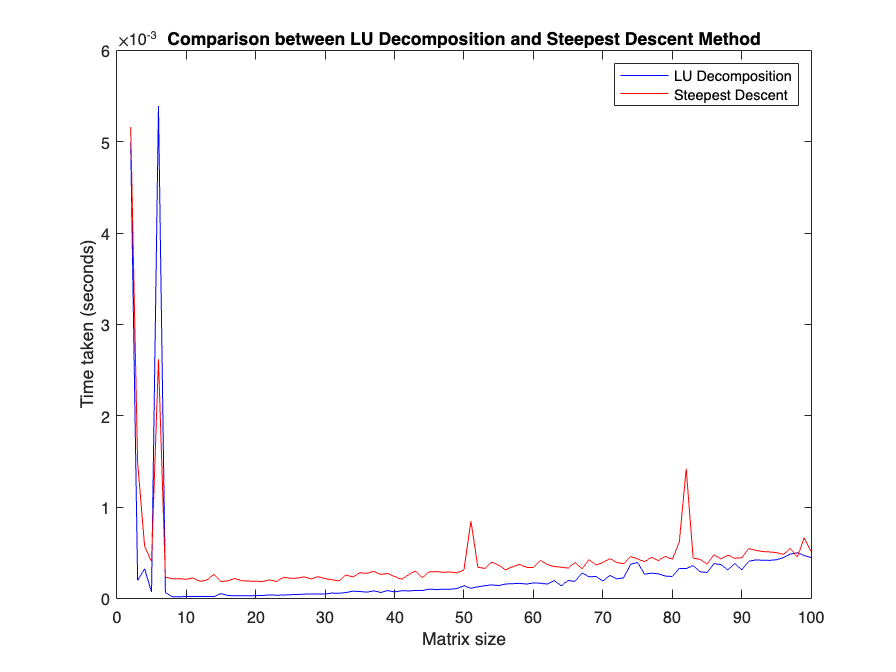

clear all
% write your code here 

% demo of how to use the method  getSystemMatrix_with_lowerConditionNumber
% for n=2

times_LU = zeros(99, 1);
times_SD = zeros(99, 1);
sizes = 2:100;

for n = sizes
    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);
    
    tic;% LU decomp 
    [L, U, P] = lu(A);
    y = L \ (P * b);
    x_LU = U \ y;
    times_LU(n-1) = toc;
   
    tol = 1e-5; % Steepest Descent
    Xguess = zeros(n, 1);
    maxiter = 10000;
    tic;
    [x_SD, ~] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    times_SD(n-1) = toc;
end

figure;
plot(sizes, times_LU, 'b-', sizes, times_SD, 'r-');
legend('LU Decomposition', 'Steepest Descent') ;
ylabel('Time taken (seconds)');
xlabel('Matrix size') ;
title('Comparison between LU Decomposition and Steepest Descent Method') ;

% COMMENT: Generally speking, the method of steepest descent takes more time than the LU decomposition one as demonstrated in the plotted graph. This is because the steepest decsent method is an iterative method compared to LU decomposition which is a direct method, in other words, the steepest descent method requires large number of iterations in order to converge to a solution and it has other implementation such as cmputation of step size, updating solution estimate, and checking for convergence. Also, in each iteration the steepest decsent method has matrix-vector multiplication whereas the LU decomposition has matrix decompositions and solving triangular. 

*d. *In this part you will repeat part c,  however, this time you need to solve the matrix systems of size ranging from n= 2 to 1000.

Similar to part c, plot the time taken by LU decomposition based solver and the steepest descent for each matrix size. Make sure your plots are properly labeled. On a seperate plot also plot the number of iterations taken by steepest decent vs matrix size.

Compare the plots from part c and d, which method takes more time to compute the solution?

Use the cell below to write your code. (5 marks)

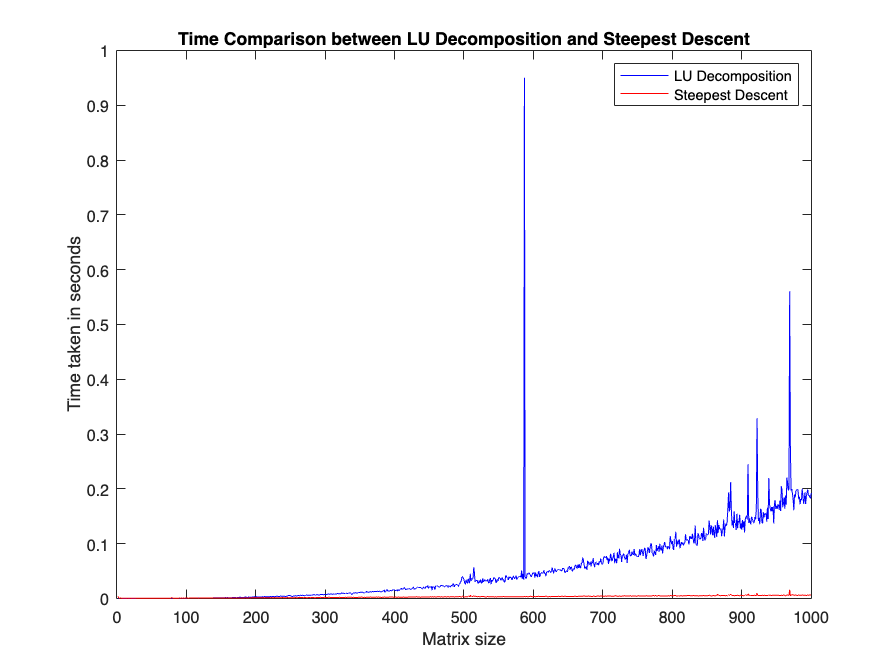

% write your code here.
clear all

times_LU = zeros(999, 1);
times_SD = zeros(999, 1);
iterations_SD = zeros(999, 1);
sizes = 2:1000;

for n = sizes
    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);
    
    tic; % LU decomp
    [L, U, P] = lu(A);
    y = L \ (P * b);
    x_LU = U \ y;
    times_LU(n-1) = toc;
    
    Xguess = zeros(n, 1); % Steepest descent
    tol = 1e-5;
    maxiter = 10000;
    tic;
    [x_SD, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    times_SD(n-1) = toc;
    iterations_SD(n-1) = iter;
end

figure; % Plot time taken for LU decomposition and Steepest Descent
plot(sizes, times_LU, 'b-', sizes, times_SD, 'r-');
title('Time Comparison between LU Decomposition and Steepest Descent');
ylabel('Time taken in seconds') ;
xlabel('Matrix size') ;
legend('LU Decomposition', 'Steepest Descent');

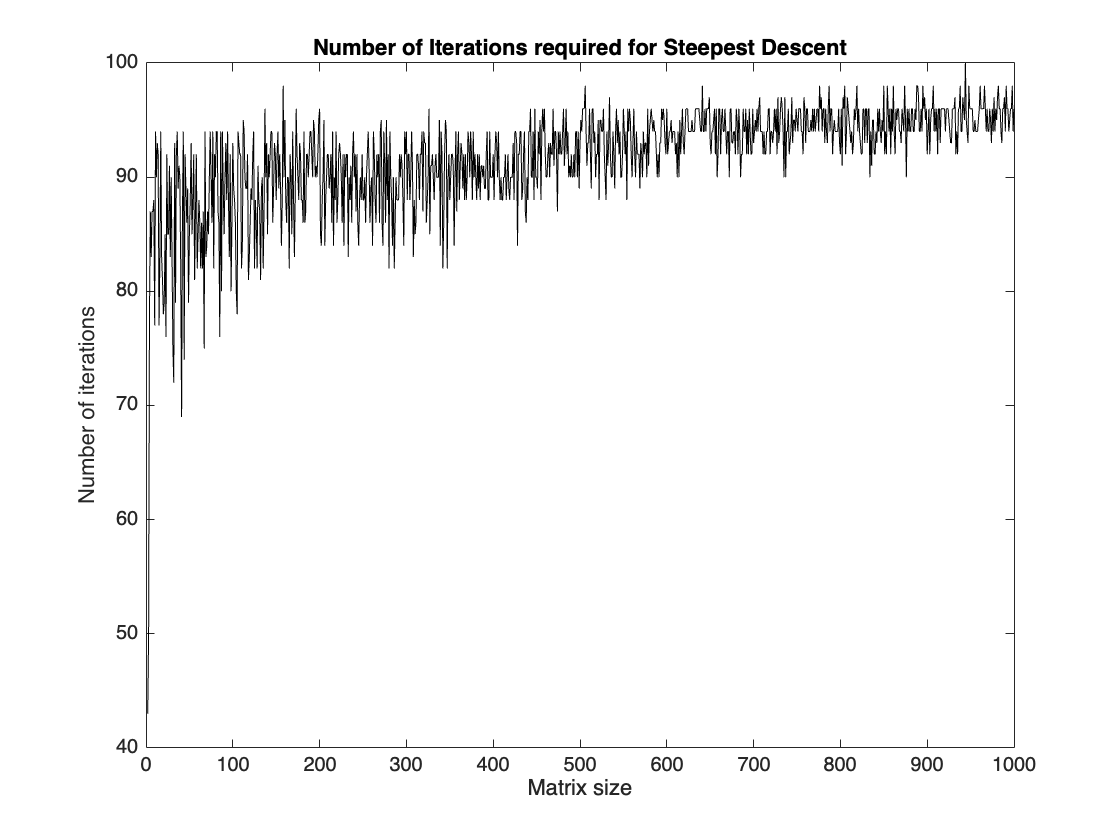


figure; % Plot number of iterations for Steepest Descent
plot(sizes, iterations_SD, 'k-');
ylabel('Number of iterations') ;
xlabel('Matrix size');
title('Number of Iterations required for Steepest Descent') ;

% COMMENT: In this part, because the matrix system size increases from 100 to 1000, it is noticeable that the time used steepest decent method is much more lower than the one of LU decomposition due to the large number of matrix size ranging. Each iteration is become more and more efficient at reducing the error with a small condition number then it leads to a requirement of fewer iterations to achieve accuracy. In contrast, the LU decomposition increases the running time substantially since it requires time for pivoting. Overall, steepest descent method uses a shorter time compared to LU decomposition, and the comparison between them becomes more obvious as matrix size increases.

e. Similar to the previous part*, *you need to solve the matrix systems of size ranging from n= 2 to 1000.  

Instead this time you will use the function *getSystemMatrix_with_higherConditionNumber *to generate the system matrix $\textbf A$* and vector *$\textbf b$*. T*he function is provided in the appendix. The function, *getSystemMatrix_with_higherConditionNumber, * generates the system matrix $\textbf A$  which has a slightly higher condition number than the matrix you used in parts c and d.

Plot the time taken by LU  decomposition based solver and the steepest descent for each matrix size. Also plot the number of iterations taken by steepest decent vs matrix size.

Comment on the similarities and difference between the  plots from part d and e.

You can use the cell below to write your code. (5 marks)

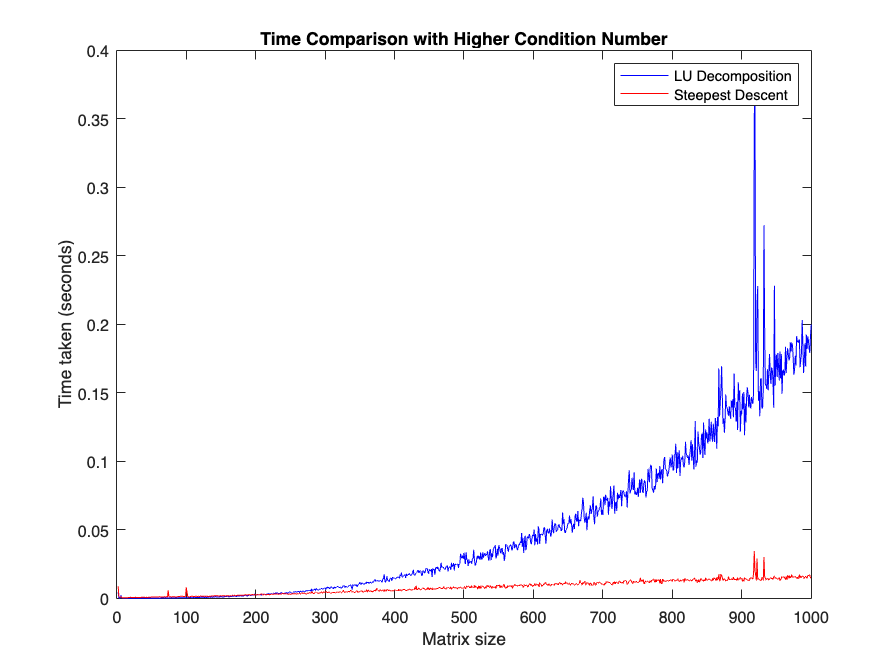

% write your code here.
clear all

% Initialize vectors to store computation times and iteration counts
times_LU = zeros(999, 1);
times_SD = zeros(999, 1);
iterations_SD = zeros(999, 1);
sizes = 2:1000;

for n = sizes
    % Generate the system matrix A and vector b with a higher condition number
    [A, b] = getSystemMatrix_with_higherConditionNumber(n);
    
    % LU decomposition and solve
    tic;
    [L, U, P] = lu(A);
    y = L \ (P * b);
    x_LU = U \ y;
    times_LU(n-1) = toc;
    
    % Steepest descent method solve
    Xguess = zeros(n, 1);
    tol = 1e-5;
    maxiter = 10000;
    tic;
    [x_SD, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter);
    times_SD(n-1) = toc;
    iterations_SD(n-1) = iter;
end

% Plot the time taken for LU decomposition and Steepest Descent
figure;
plot(sizes, times_LU, 'b-', sizes, times_SD, 'r-');
xlabel('Matrix size');
ylabel('Time taken (seconds)');
title('Time Comparison with Higher Condition Number');
legend('LU Decomposition', 'Steepest Descent');

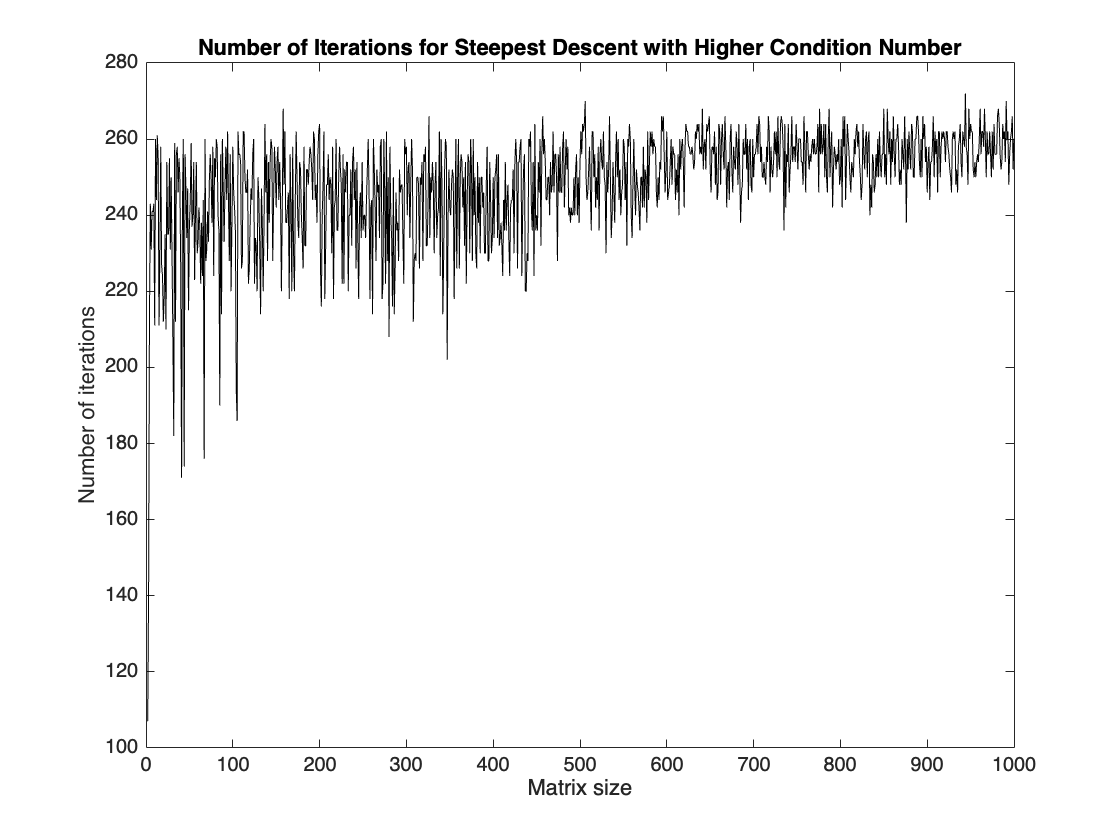


% Plot number of iterations for Steepest Descent
figure;
plot(sizes, iterations_SD, 'k-');
ylabel('Number of iterations');
xlabel('Matrix size');
title('Number of Iterations for Steepest Descent with Higher Condition Number');

% COMMENT: Both plots demonstrate that as matrix size increases, the computational time of LU decomposition increases too. And for both d) and e) the times required for Steepest descent method are much more less than LU as matrix size increases. Also, since the condition number used in this part is slighly higher than last part, we can observe that the time for Steepest descent method is resonably a bit higher than the last part. The number of iterations for Steepest Descent method with higher condition number is not that stable compared to the one with small conditin number, in other words, it varies more as shown in graph, this is because its sensitovity to the direction of the steepest descent, it becomes less aligned with the solution vector.

## Appendix 

function [A,b]= getSystemMatrix_with_lowerConditionNumber(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.25);
    A= R'*R;
    b = rand(n,1);
end

function [A,b]= getSystemMatrix_with_higherConditionNumber(n)
%  n is the size of the matrix .
% outputs: A square matrix of size n times n
%          b  vector of size n.


    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.15);
    A= R'*R;
    b = rand(n,1);
end

Write your steepest descent here.

function [x, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter)
% inputs: A- a symmeteric and positiv definite matrix.
%         b : RHS vector
%        Xguess: Initial guess 
%        tol : tolerance 
%         maxiter:maximum iterations 

%outputs:  x: solution of the system Ax =b
%          iter: number of iterations it took to converge
    x = Xguess;
    residual = b - ( A * x) ;  % Residual
    iter = 0;
    while ( (norm(residual) > tol) && ( maxiter > iter) )
        a = (residual' * residual) / (residual' * A * residual); % compute alpha - step size
        x = x + ( a * residual) ; % update guess
        residual = b - ( A * x) ; % calculate new residual
        iter = iter + 1;
    end
end

